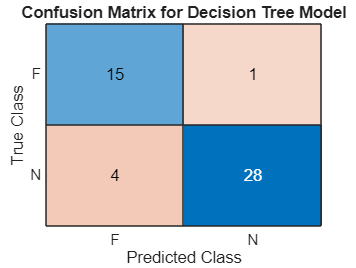

    % Train and Save Model
    
    % List training files 
    normalFiles = dir("Normal/Normal*.wav");
    faultyFiles = dir("Faulty/Faulty*.wav");
    
    numNormalSamples = length(normalFiles);
    numFaultySamples = length(faultyFiles);
    
    % Prepare input and label matrices
    xFiles = [normalFiles; faultyFiles];
    y = [repmat({'N'}, numNormalSamples, 1); repmat({'F'}, numFaultySamples, 1)];
    
    % Shuffle X and y
    numSamples = length(y);
    idx = randperm(numSamples);
    xFiles = xFiles(idx, :);
    y = y(idx);
    
    % Define the number of features
    numFeatures = 5;
    X = zeros(numSamples, numFeatures);
    
    for i = 1:numSamples
        % Define file path
        if y{i} == 'N'
            filePath = fullfile("Normal", xFiles(i).name);
        else
            filePath = fullfile("Faulty", xFiles(i).name);
        end
        
        % Read audio file
        [x, Fs] = audioread(filePath);
    
        % Feature extraction
        meanFeature = mean(x);
        stdFeature = std(x);
        windowLength = 480;
        rmsFunc = dsp.MovingRMS(windowLength);
        movingRMSFeature = mean(rmsFunc(x));
        energyFeature = sum(x .^ 2);
        zcrFeature = sum(abs(diff(x > 0))) / length(x);
    
        % Assign extracted features to X
        X(i, :) = [meanFeature, stdFeature, movingRMSFeature, energyFeature, zcrFeature];
    end
    
    % Split data and train the model
    cv = cvpartition(numSamples, 'HoldOut', 0.2);
    XTrain = X(training(cv), :);
    yTrain = y(training(cv));
    XTest = X(test(cv), :);
    yTest = y(test(cv));
    
    % Train Decision Tree model
    treeModel = fitctree(XTrain, yTrain, 'MinLeafSize', 18, 'MaxNumSplits', 50, 'SplitCriterion', 'deviance');
    
    % Predict on the test set
    predictedLabels = predict(treeModel, XTest);
    
    % Compute confusion matrix
    [confMatrix, order] = confusionmat(yTest, predictedLabels);
    
    % Display confusion matrix
    figure;
    confusionchart(confMatrix, order);
    title('Confusion Matrix for Decision Tree Model');

    
    % Calculate accuracy, precision, and recall
    accuracy = sum(diag(confMatrix)) / sum(confMatrix(:));
    precision = diag(confMatrix) ./ sum(confMatrix, 2);
    recall = diag(confMatrix) ./ sum(confMatrix, 1)';
    
    % Display results
    fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 89.58%


    fprintf('Precision for each class:\n');

Precision for each class:


    disp(precision);

    0.8750
    0.9375



    fprintf('Recall for each class:\n');

Recall for each class:


    disp(recall);

    0.9655
    0.7895



    
    % Save the trained model
    save('treeModel.mat', 'treeModel');



% Define the local API URL
url = 'http://192.168.1.109:5000/files';
options = weboptions('Timeout', 10);

% Send GET request to retrieve file details
try
    response = webread(url, options);  % Sends GET request to the API

    % Assuming the response is an array of structs
    disp('Files available on the server:');
    for i = 1:length(response)
        fprintf('Filename: %s\n', response(i).filename);
    end

catch exception
    disp('Error retrieving file details from the API:');
    disp(getReport(exception));
end

Files available on the server:


Filename: recorded_sound_0.wav
Filename: recorded_sound_1.wav
Filename: Dtmf-1.wav
Filename: recorded_sound_4.wav
Filename: recorded_sound_3.wav
Filename: recorded_sound_2.wav
Filename: Faulty1_Peak_4.wav
Filename: Faulty1_Peak_5.wav
Filename: Faulty1_Peak_6.wav
Filename: Faulty1_Peak_7.wav
Filename: Faulty1_Peak_8.wav
Filename: Faulty1_Peak_9.wav
Filename: Faulty1_Peak_10.wav
Filename: Faulty1_Peak_11.wav
Filename: Faulty1_Peak_12.wav
Filename: Faulty1_Peak_13.wav
Filename: Faulty1_Peak_14.wav
Filename: Faulty1_Peak_15.wav
Filename: Faulty1_Peak_16.wav
Filename: Faulty1_Peak_17.wav
Filename: Faulty1_Peak_18.wav
Filename: Faulty1_Peak_19.wav
Filename: Faulty1_Peak_20.wav
Filename: Faulty1_Peak_21.wav
Filename: Faulty1_Peak_22.wav
Filename: Faulty1_Peak_23.wav
Filename: Faulty1_Peak_24.wav
Filename: Faulty1_Peak_25.wav
Filename: Faulty1_Peak_26.wav
Filename: Faulty1_Peak_27.wav
Filename: Faulty1_Peak_28.wav
Filename: Faulty1_Peak_29.wav
Filename: Faulty1_Peak_30.wav
Filename: Faulty1_Pe


% Define the download URL
download_url = 'http://192.168.1.109:5000/download/Dtmf-1.wav';
output_filename = 'Normal2_Peak_25.wav';

% Download the file and save it locally
try
    websave(output_filename, download_url, options);
    disp(['File downloaded and saved as ', output_filename]);
catch exception
    disp('Error downloading the file from the API:');
    disp(getReport(exception));
end

File downloaded and saved as Normal2_Peak_25.wav



% Load the saved model
load('treeModel.mat', 'treeModel');

% Read the new audio file that was downloaded
[x, Fs] = audioread(output_filename);

% Extract features for the new audio file
meanFeature = mean(x);
stdFeature = std(x);
windowLength = 480;
rmsFunc = dsp.MovingRMS(windowLength);
movingRMSFeature = mean(rmsFunc(x));
energyFeature = sum(x .^ 2);
zcrFeature = sum(abs(diff(x > 0))) / length(x);

% Combine all extracted features into a single row
newFeatures = [meanFeature, stdFeature, movingRMSFeature, energyFeature, zcrFeature];

% Predict the label for the new audio file
predictedLabel = predict(treeModel, newFeatures);

% Display the predicted label
fprintf('Predicted Label: %s\n', predictedLabel{1});

Predicted Label: N
